# Robotics Assignment 2 - Alireza Amiri

## 0: Arash Robot FK based on the paper

%% Forward Kinematics of a Robot
% This script calculates the forward kinematics of a robotic arm.
% It defines the symbolic equations for position and rotation matrix,
% and then evaluates them numerically with variable precision.

% Clear workspace and command window
clear;
clc;

%% Define Symbolic Variables
syms phi psi d

%% Structure Parameters
% Define the lengths and angles used in the kinematic equations
l_0 = 0.006; % length 0
l_1 = 0.1820; % length 1
l_3 = 0.05; % length 3
l_5 = 0.1150; % length 5
l_2 = 0.07; % length 2
l_7 = 0.0342; % length 7
theta_value = 42 * (pi / 180); % Convert degrees to radians
alpha_value = 50 * (pi / 180); % Convert degrees to radians

%% Define Symbolic Expressions
% Define symbolic position of the end effector
P_sym = [
    sin(theta_value) * cos(psi + alpha_value) * d + ...
    cos(theta_value) * cos(phi) * sin(psi + alpha_value) * d + ...
    sin(theta_value) * (l_1 + l_3 + l_5);
    
    sin(phi) * sin(psi + alpha_value) * d;
    
    cos(theta_value) * cos(psi + alpha_value) * d - ...
    cos(phi) * sin(theta_value) * sin(psi + alpha_value) * d + ...
    cos(theta_value) * (l_1 + l_3 + l_5)
];

% Define symbolic rotation matrix
R_sym = [
    cos(theta_value) * cos(phi) * cos(psi + alpha_value) - ...
    sin(theta_value) * sin(psi + alpha_value), ...
    -cos(theta_value) * sin(phi), ...
    cos(theta_value) * cos(phi) * sin(psi + alpha_value) + ...
    sin(theta_value) * cos(psi + alpha_value);
    
    sin(phi) * cos(psi + alpha_value), ...
    cos(phi), ...
    sin(phi) * sin(psi + alpha_value);
    
    -sin(theta_value) * cos(phi) * cos(psi + alpha_value) - ...
    cos(theta_value) * sin(psi + alpha_value), ...
    -sin(theta_value) * sin(phi), ...
    -sin(theta_value) * cos(phi) * sin(psi + alpha_value) + ...
    cos(theta_value) * cos(psi + alpha_value)
];

%% Simplify Symbolic Results
% Simplify the symbolic position and rotation matrix
P_sym_simplified = vpa(P_sym,4);
R_sym_simplified = vpa(R_sym,4);

%% Display Simplified Symbolic Results
disp('Simplified Symbolic Position of the End Effector:');

Simplified Symbolic Position of the End Effector:


disp(P_sym_simplified);

$$\left(\begin{array}{c} 0.6691\,d\,\cos\left(\psi +0.8727\right)+0.7431\,d\,\sin\left(\psi +0.8727\right)\,\cos\left(\varphi \right)+0.2322\\ d\,\sin\left(\psi +0.8727\right)\,\sin\left(\varphi \right)\\ 0.7431\,d\,\cos\left(\psi +0.8727\right)-0.6691\,d\,\sin\left(\psi +0.8727\right)\,\cos\left(\varphi \right)+0.2579 \end{array}\right)$$


disp('Simplified Symbolic Rotation Matrix of the End Effector:');

Simplified Symbolic Rotation Matrix of the End Effector:


disp(R_sym_simplified);

$$\left(\begin{array}{ccc} 0.7431\,\cos\left(\psi +0.8727\right)\,\cos\left(\varphi \right)-0.6691\,\sin\left(\psi +0.8727\right) & -0.7431\,\sin\left(\varphi \right) & 0.6691\,\cos\left(\psi +0.8727\right)+0.7431\,\sin\left(\psi +0.8727\right)\,\cos\left(\varphi \right)\\ \cos\left(\psi +0.8727\right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right) & \sin\left(\psi +0.8727\right)\,\sin\left(\varphi \right)\\ -0.7431\,\sin\left(\psi +0.8727\right)-0.6691\,\cos\left(\psi +0.8727\right)\,\cos\left(\varphi \right) & -0.6691\,\sin\left(\varphi \right) & 0.7431\,\cos\left(\psi +0.8727\right)-0.6691\,\sin\left(\psi +0.8727\right)\,\cos\left(\varphi \right) \end{array}\right)$$


%% Define Numerical Values
% Specify numerical values for the joint parameters
phi_num = pi / 4; % Example value for phi (radians)
psi_num = pi / 6; % Example value for psi (radians)
d_num = 0.1;      % Example value for d

%% Numerical Evaluation
% Substitute numerical values into symbolic expressions
P_eval = subs(P_sym_simplified, [phi, psi, d], [phi_num, psi_num, d_num]);
R_eval = subs(R_sym_simplified, [phi, psi, d], [phi_num, psi_num, d_num]);

% Use vpa for variable precision arithmetic
P_eval_vpa = vpa(P_eval, 5); % 5 significant digits
R_eval_vpa = vpa(R_eval, 5); % 5 significant digits

% Display Numerical Results
disp('Numerical Position of the End Effector (with vpa):');

Numerical Position of the End Effector (with vpa):


disp(P_eval_vpa);

$$\left(\begin{array}{c} 0.29556\\ 0.069636\\ 0.22418 \end{array}\right)$$


disp('Numerical Rotation Matrix of the End Effector (with vpa):');

Numerical Rotation Matrix of the End Effector (with vpa):


disp(R_eval_vpa);

$$\left(\begin{array}{ccc} -0.56772 & -0.52548 & 0.63369\\ 0.12279 & 0.70711 & 0.69636\\ -0.81402 & -0.47315 & -0.33691 \end{array}\right)$$

### 2.1 . Forward Kinematics of Arash Assist Robot

% Part 1: Symbolic Calculations

% Define symbolic angles for the first section
syms theta phi L1234

% Step 1: Define symbolic rotation matrices for the required axes
% Rotation about the fixed Y-axis (Ry(theta))
Ry_theta = [cos(theta),  0, sin(theta);
             0,          1, 0;
             -sin(theta), 0, cos(theta)];

% Rotation about the new Z-axis (Rz(phi))
Rz_phi = [cos(phi), -sin(phi), 0;
           sin(phi),  cos(phi), 0;
           0,           0,          1];

% Display rotation matrices
disp('Rotation matrix around fixed Y-axis (Ry(theta)):' );

Rotation matrix around fixed Y-axis (Ry(theta)):


disp(Ry_theta);

$$\left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$


disp('Rotation matrix around new Z-axis (Rz(phi)):' );

Rotation matrix around new Z-axis (Rz(phi)):


disp(Rz_phi);

$$\left(\begin{array}{ccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


% Step 2: Define the initial position of Point A
P_A_initial = [0; 0; L1234]  % Position of Point A in homogeneous coordinates

$$P\_A\_initial = \left(\begin{array}{c} 0\\ 0\\ L_{1234} \end{array}\right)$$


% Step 3: Compute the new position of Point A
R_combined = Rz_phi * Ry_theta;
P_A_new = R_combined * P_A_initial;

% Display new position of Point A symbolically
disp('New position of Point A (P_A_new):');

New position of Point A (P_A_new):


disp(P_A_new);

$$\left(\begin{array}{c} L_{1234}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ L_{1234}\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ L_{1234}\,\cos\left(\theta \right) \end{array}\right)$$


% Define symbolic angles for the second section
syms theta_d phi_d alpha psi d

% Step 1: Define symbolic rotation matrices for the required axes
% Rotation about the fixed Y-axis (Ry(theta_d))
Ry_theta_d = [cos(theta_d),  0, sin(theta_d);
               0,           1, 0;
               -sin(theta_d), 0, cos(theta_d)];

% Rotation about the new Z-axis (Rz(phi_d))
Rz_phi_d = [cos(phi_d), -sin(phi_d), 0;
             sin(phi_d),  cos(phi_d), 0;
             0,           0,          1];

% Rotation about the Y-axis (Ry(alpha + psi))
Rv_alpha_plus_psi = [cos(alpha + psi), 0, sin(alpha + psi);
                      0,               1, 0;
                     -sin(alpha + psi), 0, cos(alpha + psi)];

% Display rotation matrices
disp('Rotation matrix around fixed Y-axis (Ry(theta_d)):' );

Rotation matrix around fixed Y-axis (Ry(theta_d)):


disp(Ry_theta_d);

$$\left(\begin{array}{ccc} \cos\left(\theta_{d}\right) & 0 & \sin\left(\theta_{d}\right)\\ 0 & 1 & 0\\ -\sin\left(\theta_{d}\right) & 0 & \cos\left(\theta_{d}\right) \end{array}\right)$$


disp('Rotation matrix around new Z-axis (Rz(phi_d)):' );

Rotation matrix around new Z-axis (Rz(phi_d)):


disp(Rz_phi_d);

$$\left(\begin{array}{ccc} \cos\left(\varphi_{d}\right) & -\sin\left(\varphi_{d}\right) & 0\\ \sin\left(\varphi_{d}\right) & \cos\left(\varphi_{d}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


disp('Rotation matrix around Y-axis (Ry(alpha + psi)):' );

Rotation matrix around Y-axis (Ry(alpha + psi)):


disp(Rv_alpha_plus_psi);

$$\left(\begin{array}{ccc} \cos\left(\alpha +\psi \right) & 0 & \sin\left(\alpha +\psi \right)\\ 0 & 1 & 0\\ -\sin\left(\alpha +\psi \right) & 0 & \cos\left(\alpha +\psi \right) \end{array}\right)$$


% Step 2: Define the position vector
d_vector = [0; 0; d]  % Position of Point D as a symbolic vector

$$d\_vector = \left(\begin{array}{c} 0\\ 0\\ d \end{array}\right)$$


% Step 3: Compute the total rotation matrix
R_total = Rv_alpha_plus_psi * Rz_phi_d * Ry_theta_d;
P_D_new = R_total * d_vector;

% Display new position of Point D symbolically
disp('New position of Point D (P_D_new):');

New position of Point D (P_D_new):


disp(P_D_new);

$$\left(\begin{array}{c} d\,\left(\sin\left(\alpha +\psi \right)\,\cos\left(\theta_{d}\right)+\cos\left(\alpha +\psi \right)\,\cos\left(\varphi_{d}\right)\,\sin\left(\theta_{d}\right)\right)\\ d\,\sin\left(\varphi_{d}\right)\,\sin\left(\theta_{d}\right)\\ d\,\left(\cos\left(\alpha +\psi \right)\,\cos\left(\theta_{d}\right)-\sin\left(\alpha +\psi \right)\,\cos\left(\varphi_{d}\right)\,\sin\left(\theta_{d}\right)\right) \end{array}\right)$$

disp(R_total)

$$\left(\begin{array}{ccc} \cos\left(\alpha +\psi \right)\,\cos\left(\varphi_{d}\right)\,\cos\left(\theta_{d}\right)-\sin\left(\alpha +\psi \right)\,\sin\left(\theta_{d}\right) & -\cos\left(\alpha +\psi \right)\,\sin\left(\varphi_{d}\right) & \sin\left(\alpha +\psi \right)\,\cos\left(\theta_{d}\right)+\cos\left(\alpha +\psi \right)\,\cos\left(\varphi_{d}\right)\,\sin\left(\theta_{d}\right)\\ \cos\left(\theta_{d}\right)\,\sin\left(\varphi_{d}\right) & \cos\left(\varphi_{d}\right) & \sin\left(\varphi_{d}\right)\,\sin\left(\theta_{d}\right)\\ -\cos\left(\alpha +\psi \right)\,\sin\left(\theta_{d}\right)-\sin\left(\alpha +\psi \right)\,\cos\left(\varphi_{d}\right)\,\cos\left(\theta_{d}\right) & \sin\left(\alpha +\psi \right)\,\sin\left(\varphi_{d}\right) & \cos\left(\alpha +\psi \right)\,\cos\left(\theta_{d}\right)-\sin\left(\alpha +\psi \right)\,\cos\left(\varphi_{d}\right)\,\sin\left(\theta_{d}\right) \end{array}\right)$$

% Step 2: Summing the symbolic positions
P_total_symbolic = P_A_new + P_D_new;

% Display total symbolic position
disp('Total symbolic position (P_A_new + P_D_new):');

Total symbolic position (P_A_new + P_D_new):


disp(P_total_symbolic);

$$\left(\begin{array}{c} d\,\left(\sin\left(\alpha +\psi \right)\,\cos\left(\theta_{d}\right)+\cos\left(\alpha +\psi \right)\,\cos\left(\varphi_{d}\right)\,\sin\left(\theta_{d}\right)\right)+L_{1234}\,\cos\left(\varphi \right)\,\sin\left(\theta \right)\\ L_{1234}\,\sin\left(\varphi \right)\,\sin\left(\theta \right)+d\,\sin\left(\varphi_{d}\right)\,\sin\left(\theta_{d}\right)\\ L_{1234}\,\cos\left(\theta \right)+d\,\left(\cos\left(\alpha +\psi \right)\,\cos\left(\theta_{d}\right)-\sin\left(\alpha +\psi \right)\,\cos\left(\varphi_{d}\right)\,\sin\left(\theta_{d}\right)\right) \end{array}\right)$$

% Part 2: Numerical Calculations

% Step 4: Assign numerical values to theta and phi for Part 1
theta_val = deg2rad(45);  % Example: theta = 22.23 degrees
phi_val = deg2rad(45);    % Example: phi = -4.11 degrees

% Substitute numerical values into the rotation matrices
Ry_theta_numeric = double(subs(Ry_theta, theta, theta_val));
Rz_phi_numeric = double(subs(Rz_phi, phi, phi_val));

% Substitute numerical values into the initial position vector
P_A_initial_numeric = [0; 0; 0.347];  % Fixed length for L1234 (here set to 34.7.0 for example)

% Compute the new position numerically for Point A
P_A_new_numeric = Rz_phi_numeric * Ry_theta_numeric * P_A_initial_numeric;

% Display the final numerical position for Point A
fprintf('New position of Point A with numerical values (theta = %.2f, phi = %.2f):\n', theta_val, phi_val);

New position of Point A with numerical values (theta = 0.79, phi = 0.79):


disp(P_A_new_numeric);

    0.1735
    0.1735
    0.2454




% Step 4: Assign numerical values for the second part
theta_d_val = deg2rad(42);  % Example: theta_d = 30 degrees
phi_d_val = deg2rad(45);    % Example: phi_d = 45 degrees
alpha_val = deg2rad(50);     % Example: alpha = 10 degrees
psi_val = deg2rad(30);       % Example: psi = 20 degrees
d_val = 0.1;                 % Example fixed length for d

% Substitute numerical values into the rotation matrices for Part 2
Ry_theta_d_numeric = double(subs(Ry_theta_d, theta_d, theta_d_val));
Rz_phi_d_numeric = double(subs(Rz_phi_d, phi_d, phi_d_val));
Rv_alpha_plus_psi_numeric = double(subs(Rv_alpha_plus_psi, [alpha, psi], [alpha_val, psi_val]));

% Substitute numerical values into the position vector
d_vector_numeric = [0; 0; d_val];  % Fixed length for d

% Compute the new position numerically for Point D
P_D_new_numeric = Rv_alpha_plus_psi_numeric * Rz_phi_d_numeric * Ry_theta_d_numeric * d_vector_numeric;

% Display the final numerical position for Point D
fprintf('New position of Point D with numerical values:\n');

New position of Point D with numerical values:


disp(P_D_new_numeric);

    0.0814
    0.0473
   -0.0337




% Step 5: Summing the numerical positions
P_total_numeric = P_A_new_numeric + P_D_new_numeric;

% Display total numerical position
fprintf('Total numerical position (P_A_new_numeric + P_D_new_numeric):\n');

Total numerical position (P_A_new_numeric + P_D_new_numeric):


disp(P_total_numeric);

    0.2549
    0.2208
    0.2117



### 2.2: PRR robot

#### 2.2.1: Closed Loop Method

% Step 1: Define symbolic variables
syms d1 theta2 theta3 a2 a3 real;

% Step 2: Define the equations for end effector position and orientation
xe = d1 + a2 * cos(theta2) + a3 * cos(theta2 + theta3);
ye = a2 * sin(theta2) + a3 * sin(theta2 + theta3);
theta_e = theta2 + theta3;

% Step 3: Display symbolic equations
disp('Symbolic equations:');

Symbolic equations:


disp('xe =');

xe =


disp(xe);

$$d_{1}+a_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+a_{2}\,\cos\left(\theta_{2}\right)$$

disp('ye =');

ye =


disp(ye);

$$a_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+a_{2}\,\sin\left(\theta_{2}\right)$$

disp('theta_e =');

theta_e =


disp(theta_e);

$$\theta_{2}+\theta_{3}$$


% Step 4: Substitute numerical values
% Example values for d1, theta2, theta3, a2, and a3
d1_value = 2;         % Example value for d1
theta2_value = pi/4;  % Example value for theta2 (45 degrees)
theta3_value = pi/6;  % Example value for theta3 (30 degrees)
a2_value = 1;         % Example value for a2
a3_value = 1;         % Example value for a3

% Step 5: Substitute numerical values into the equations
xe_numeric = subs(xe, [d1, theta2, theta3, a2, a3], [d1_value, theta2_value, theta3_value, a2_value, a3_value]);
ye_numeric = subs(ye, [d1, theta2, theta3, a2, a3], [d1_value, theta2_value, theta3_value, a2_value, a3_value]);
theta_e_numeric = subs(theta_e, [theta2, theta3], [theta2_value, theta3_value]);

% Step 6: Display the numerical results
disp('Numerical results:');

Numerical results:


disp('xe =');

xe =


disp(xe_numeric);

$$\frac{\sqrt{2}}{4}+\frac{\sqrt{6}}{4}+2$$

disp('ye =');

ye =


disp(ye_numeric);

$$\frac{3\,\sqrt{2}}{4}+\frac{\sqrt{6}}{4}$$

disp('theta_e =');

theta_e =


disp(theta_e_numeric);

$$\frac{5\,\pi }{12}$$

#### 2.2.2: DH

syms theta1 theta2 theta3 d1 a2 a3 real

T1 = DH(0, 0, d1, 0);     % Homogeneous Transformation
T2 = DH(a2, 0, 0, theta2);
T3 = DH(a3, 0, 0, theta3);
T1 = Matrix_Vpa(T1, 4, 4);       % Remove very small coefficients
T_Final = T1 * simplify(T2 * T3) % Final Homogeneous Transformation

$$T\_Final = \left(\begin{array}{cccc} 1.0\,\cos\left(\theta_{2}+\theta_{3}\right) & -1.0\,\sin\left(\theta_{2}+\theta_{3}\right) & 0 & 1.0\,a_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+1.0\,a_{2}\,\cos\left(\theta_{2}\right)\\ 1.0\,\sin\left(\theta_{2}+\theta_{3}\right) & 1.0\,\cos\left(\theta_{2}+\theta_{3}\right) & 0 & 1.0\,a_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)+1.0\,a_{2}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1.0 & 1.0\,d_{1}\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

#### 2.2.3: Screw based Method

[S] = SR(s_x, s_y, s_z, s_ox, s_oy, s_oz, theta, d)

% Step 1: Define symbolic variables
syms theta1 theta2 theta3 d1 a1 a2 a3 real;

% Define the screw-based transformations
S1 = SR(1, 0, 0, 0, 0, 0, 0, d1); % Screw-based Homogeneous Transformation for joint 1
S2 = SR(0, 0, 1, a1, 0, 0, theta2, 0); % Screw-based Homogeneous Transformation for joint 2
S3 = SR(0, 0, 1, a1 + a2, 0, 0, theta3, 0); % Screw-based Homogeneous Transformation for joint 3

Screw = simplify(S1 * simplify(S2 * S3)) % Compound Transformation

$$Screw = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{2}+\theta_{3}\right) & 0 & d_{1}-a_{1}\,\left(\cos\left(\theta_{2}\right)-1\right)+\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\left(a_{1}+a_{2}\right)-\cos\left(\theta_{2}\right)\,\left(a_{1}+a_{2}\right)\,\left(\cos\left(\theta_{3}\right)-1\right)\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & -a_{1}\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\left(a_{1}+a_{2}\right)-\sin\left(\theta_{2}\right)\,\left(a_{1}+a_{2}\right)\,\left(\cos\left(\theta_{3}\right)-1\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Display the symbolic Screw transformation
disp('Compound Screw Transformation (Symbolic):');

Compound Screw Transformation (Symbolic):


disp(Screw);

$$\left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{2}+\theta_{3}\right) & 0 & d_{1}-a_{1}\,\left(\cos\left(\theta_{2}\right)-1\right)+\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\left(a_{1}+a_{2}\right)-\cos\left(\theta_{2}\right)\,\left(a_{1}+a_{2}\right)\,\left(\cos\left(\theta_{3}\right)-1\right)\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & -a_{1}\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\left(a_{1}+a_{2}\right)-\sin\left(\theta_{2}\right)\,\left(a_{1}+a_{2}\right)\,\left(\cos\left(\theta_{3}\right)-1\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

U0 = [1; 0; 0];
V0 = [0; 1; 0];
W0 = [0; 0; 1];
E0 = [a2 + a3; 0; 0];
S0 = [U0, V0, W0, E0;
0, 0, 0, 1]; % Initial state HT
display(S0)

$$S0 = \left(\begin{array}{cccc} 1 & 0 & 0 & a_{2}+a_{3}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


S_Final = Screw * S0;
R_SR = S_Final(1:3, 1:3); % Orientation of end effector
P_SR = S_Final(1:3, 4); % Position of end effector

disp('Final End-Effector Position (Screw method):')

Final End-Effector Position (Screw method):



P_SR = simplify(P_SR)

$$P\_SR = \left(\begin{array}{c} a_{1}+d_{1}-a_{1}\,\cos\left(\theta_{2}+\theta_{3}\right)+a_{3}\,\cos\left(\theta_{2}+\theta_{3}\right)+a_{2}\,\cos\left(\theta_{2}\right)\\ a_{3}\,\sin\left(\theta_{2}+\theta_{3}\right)-a_{1}\,\sin\left(\theta_{2}+\theta_{3}\right)+a_{2}\,\sin\left(\theta_{2}\right)\\ 0 \end{array}\right)$$

S_Final

$$S\_Final = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{2}+\theta_{3}\right) & 0 & d_{1}+\cos\left(\theta_{2}+\theta_{3}\right)\,\left(a_{2}+a_{3}\right)-a_{1}\,\left(\cos\left(\theta_{2}\right)-1\right)+\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\left(a_{1}+a_{2}\right)-\cos\left(\theta_{2}\right)\,\left(a_{1}+a_{2}\right)\,\left(\cos\left(\theta_{3}\right)-1\right)\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & \sin\left(\theta_{2}+\theta_{3}\right)\,\left(a_{2}+a_{3}\right)-a_{1}\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\,\left(a_{1}+a_{2}\right)-\sin\left(\theta_{2}\right)\,\left(a_{1}+a_{2}\right)\,\left(\cos\left(\theta_{3}\right)-1\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Error_T = simplify(S_Final - T_Final)

$$Error\_T = \left(\begin{array}{cccc} 0 & 0 & 0 & a_{1}+d_{1}-a_{1}\,\cos\left(\theta_{2}+\theta_{3}\right)\\ 0 & 0 & 0 & -1.0\,a_{1}\,\sin\left(\theta_{2}+\theta_{3}\right)\\ 0 & 0 & 0 & -1.0\,d_{1}\\ 0 & 0 & 0 & 0 \end{array}\right)$$

#### 2.3.4: Work Space

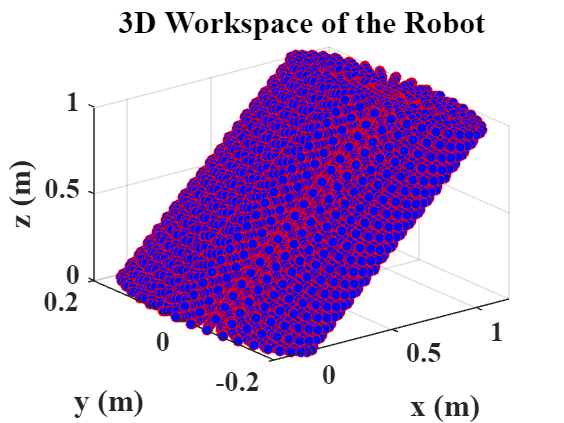

% Step 1: Define symbolic variables for joint angles and link lengths
syms d1 theta2 theta3 a2 a3 real;

% Define numeric values for link lengths
a2_val = 0.1;  % Example value for a2 (in meters)
a3_val = 0.1;   % Example value for a3 (in meters)

% Define the range of values for joint variables
N = 20;  % Number of points for each variable (reduced for faster plotting)
theta2_vals = linspace(-pi, pi, N);  % Range for theta2
theta3_vals = linspace(-pi, pi, N);  % Range for theta3
d1_vals = linspace(0, 1, N);        % Range for d1 (negative depth)

% Initialize arrays for storing positions
px = [];
py = [];
pz = [];

% Step 2: Compute reachable positions by substituting numeric values
for theta2_val = theta2_vals
    for theta3_val = theta3_vals
        for d1_val = d1_vals
            % Substitute values into the end-effector equations
            xe = subs(d1 + a2 * cos(theta2) + a3 * cos(theta2 + theta3), ...
                      {d1, theta2, theta3, a2, a3}, ...
                      {d1_val, theta2_val, theta3_val, a2_val, a3_val});
                  
            ye = subs(a2 * sin(theta2) + a3 * sin(theta2 + theta3), ...
                      {theta2, theta3, a2, a3}, ...
                      {theta2_val, theta3_val, a2_val, a3_val});
                  
            % Store the positions (z-axis assumed as d1 values)
            px = [px, double(xe)];
            py = [py, double(ye)];
            pz = [pz, double(d1_val)];
        end
    end
end

% Step 3: Plot the 3D workspace
figure;
scatter3(px, py, pz, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'blue');
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
set(gca, 'FontWeight', 'bold', 'FontName', 'times', 'FontSize', 17);
title('3D Workspace of the Robot');
grid on;

### 2.3: Kuka IIWA robot

#### 2.3.1: DH method_ Complete

% Define symbolic variables for joint angles and link offsets
syms theta1 theta2 theta3 theta4 theta5 theta6 theta7 real
syms d1 d2 d3 d4 d5 d6 d7 real

% Define each transformation matrix based on DH parameters
T1 = DH(0, -pi/2, d1, theta1);
T2 = DH(0, pi/2, 0, theta2);
T3 = DH(0, pi/2, d3, theta3);
T4 = DH(0, -pi/2, 0, theta4);
T5 = DH(0, -pi/2, d5, theta5);
T6 = DH(0, pi/2, 0, theta6);
T7 = DH(0, 0, d7, theta7);

% Convert each matrix to decimal approximation using Matrix_Vpa
T1 = Matrix_Vpa(T1, 4, 4);
T2 = Matrix_Vpa(T2, 4, 4);
T3 = Matrix_Vpa(T3, 4, 4);
T4 = Matrix_Vpa(T4, 4, 4);
T5 = Matrix_Vpa(T5, 4, 4);
T6 = Matrix_Vpa(T6, 4, 4);
T7 = Matrix_Vpa(T7, 4, 4);

% Step-by-step two-by-two multiplication and simplification
T12 = simplify(T1 * T2);               % Multiply T1 and T2, then simplify
T34 = simplify(T3 * T4);               % Multiply T3 and T4, then simplify
T56 = simplify(T5 * T6);               % Multiply T5 and T6, then simplify

% Further multiplication of intermediate matrices
T1234 = simplify(T12 * T34);           % Multiply T12 and T34, then simplify
T123456 = simplify(T1234 * T56);       % Multiply T1234 and T56, then simplify
T_Final = simplify(T123456 * T7);      % Final multiplication with T7

% Display the final simplified transformation matrix in symbolic form
disp('Final Transformation Matrix T_Final (Simplified):');

Final Transformation Matrix T_Final (Simplified):


disp(T_Final);


% Convert final matrix to decimal form using Matrix_Vpa
T_Final_vpa = Matrix_Vpa(T_Final, 4, 4);

% Display the numerical transformation matrix
disp('Final Transformation Matrix T_Final (Numeric, 4 decimal places):');

Final Transformation Matrix T_Final (Numeric, 4 decimal places):


disp(T_Final_vpa);

#### 2.3.2: Screw methods_ Complete

% Define symbolic variables for joint angles and link lengths
syms theta1 theta2 theta3 theta4 theta5 theta6 theta7 a1 a3 a5 real;

% Define each screw transformation
S1 = SR(0, 0, 1, 0, 0, 0, theta1, 0);       % Joint 1
S2 = SR(0, 1, 0, 0, 0, a1, theta2, 0);      % Joint 2
S3 = SR(0, -1, 0, 0, 0, 0, theta3, 0);      % Joint 3
S4 = SR(0, 1, 0, 0, 0, a1 + a3, theta4, 0); % Joint 4
S5 = SR(0, 0, 1, 0, 0, 0, theta5, 0);       % Joint 5
S6 = SR(0, 1, 0, 0, 0, a1 + a3 + a5, theta6, 0); % Joint 6
S7 = SR(0, 0, 1, 0, 0, 0, theta7, 0);       % Joint 7

% Pairwise multiplication and simplification of transformations
S12 = simplify(S1 * S2); % Compound Transformation for joints 1 and 2
S34 = simplify(S3 * S4); % Compound Transformation for joints 3 and 4
S56 = simplify(S5 * S6); % Compound Transformation for joints 5 and 6

% Compound transformation of pairs
S1234 = simplify(S12 * S34);        % Compound Transformation for joints 1 to 4
S123456 = simplify(S1234 * S56);    % Compound Transformation for joints 1 to 6

% Final transformation including joint 7
T_Final = simplify(S123456 * S7);   % Compound Transformation for the entire manipulator

% Additional compound transformations if needed
S13 = simplify(S12 * S3);           % Compound Transformation for joints 1, 2, and 3

% Display final transformation
disp('Final Transformation Matrix T_Final:')

Final Transformation Matrix T_Final:


disp(T_Final);

#### 2.3.4: First 3 degrees

% Define symbolic variables (assuming they are defined)
syms d1 d3 theta1 theta2 theta3 a1 real;

% DH Transformations
T1 = DH(0, -pi/2, a1, theta1);
T2 = DH(0, pi/2, 0, theta2);
T3 = DH(0, pi/2, a3, theta3);

% Simplify and convert each DH transformation to numerical approximation
T1 = Matrix_Vpa(T1, 4, 4);
T2 = Matrix_Vpa(T2, 4, 4);
T3 = Matrix_Vpa(T3, 4, 4);

% Compound Transformation for DH
T_DH = simplify(T1 * T2 * T3);

disp('Compound Transformation for DH (T_DH):');

Compound Transformation for DH (T_DH):


disp(T_DH);

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-1.0\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)+\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & a_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right) & a_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -1.0\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & -1.0\,\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & a_{1}+a_{3}\,\cos\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

% Screw Transformations
S1 = SR(0, 0, 1, 0, 0, 0, theta1, 0);        % Joint 1
S2 = SR(0, 1, 0, 0, 0, a1, theta2, 0);       % Joint 2
S3 = SR(0, 0, 1, 0, 0, 0, theta3, 0);       % Joint 3

% Compound Transformation for Screw
S_Screw_0_3 = simplify(S1 * S2 * S3);
disp('Compound Transformation for Screw (S_Screw):');

Compound Transformation for Screw (S_Screw):


disp(S_Screw_0_3);

$$\left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -a_{1}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & -a_{1}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{2}\right) & -a_{1}\,\left(\cos\left(\theta_{2}\right)-1\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

U0 = [1; 0; 0];
V0 = [0; 1; 0];
W0 = [0; 0; 1];
E0 = [0; 0; a1 + a3];
S0 = [U0, V0, W0, E0;
0, 0, 0, 1]; % Initial state HT

display(S0)

$$S0 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & a_{1}+a_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

S_Final = S_Screw_0_3 * S0;
R_SR = S_Final(1:3, 1:3); % Orientation of end effector
P_SR = S_Final(1:3, 4); % Position of end effector

disp('Final End-Effector Position (Screw method):')

Final End-Effector Position (Screw method):


S_Final

$$S\_Final = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{1}+a_{3}\right)-a_{1}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\,\left(a_{1}+a_{3}\right)-a_{1}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{2}\right) & \cos\left(\theta_{2}\right)\,\left(a_{1}+a_{3}\right)-a_{1}\,\left(\cos\left(\theta_{2}\right)-1\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

P_SR = simplify(P_SR)

$$P\_SR = \left(\begin{array}{c} a_{3}\,\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ a_{3}\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ a_{1}+a_{3}\,\cos\left(\theta_{2}\right) \end{array}\right)$$

R_SR

$$R\_SR = \left(\begin{array}{ccc} \cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)-\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)-\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \cos\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)+\cos\left(\theta_{2}\right)\,\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right) & \sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ -\cos\left(\theta_{3}\right)\,\sin\left(\theta_{2}\right) & \sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right) & \cos\left(\theta_{2}\right) \end{array}\right)$$

Error_T = simplify(S_Final - T_DH)

$$Error\_T = \begin{array}{l} \left(\begin{array}{cccc} 0 & -\sigma_{6}-\sigma_{5}-\sigma_{2} & \sigma_{6}-\sigma_{5}-\sigma_{2} & 0\\ 0 & \sigma_{7}-\sigma_{4}-\sigma_{1} & \sigma_{7}+\sigma_{4}-\sigma_{1} & 0\\ 0 & \sigma_{3}-\cos\left(\theta_{2}\right) & \cos\left(\theta_{2}\right)+\sigma_{3} & 0\\ 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{2}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{3}=\sin\left(\theta_{2}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{4}=\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{5}=\cos\left(\theta_{3}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{6}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)\\ \sigma_{7}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{3}\right) \end{array}$$